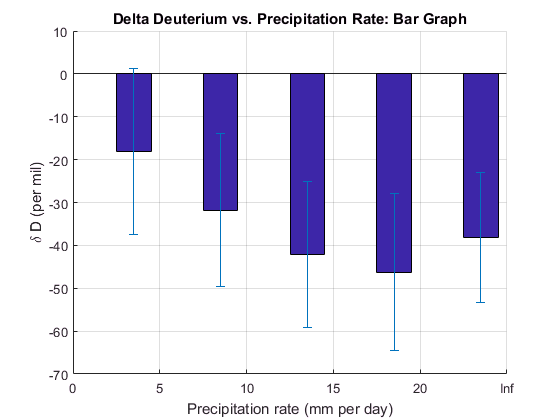

[pppdaybin_w,Edges_w]= discretize(pppdayTable_w,[0,5,10,15,20,Inf]);

%I want to get the array of deltaH2 for each bin
for i=1:(length(Edges_w)-1)
 %I use a structure as it is easier to use with loops
H2binned_w(i).H2=H2_w(pppdaybin_w == i);
end

for i=1:(length(Edges_w)-1)
    %I then find the mean of these deltaH2 (along with the standard deviations
    H2binned_w(i).mean = nanmean(cell2mat(H2binned_w(i).H2));
    H2binned_w(i).error = nanstd(cell2mat(H2binned_w(i).H2));
end

MidEdge(1,:)=Edges_w(1:(length(Edges_w)-1));
MidEdge(2,:)=Edges_w(2:length(Edges_w));
MidEdge=mean(MidEdge);
%Redefining the mid edge for the final bin
MidEdge(length(Edges_w)-1)=MidEdge(1)+Edges_w(length(Edges_w)-1);

if 1<=i && i<=6
    MidEdgeShift=1;
else
    MidEdgeShift=-1;
end

tabForH2=struct2table(H2binned_w); %onvert to table, in order to access 
                                   % the data when producing a graph

figure(i)
pointPosn=MidEdge+MidEdgeShift;
hold on
b=bar(pointPosn,tabForH2.mean);
b.BarWidth=0.4;

%We also want to include errors, so we create an error bars object
e=errorbar(pointPosn,tabForH2.mean,tabForH2.error);
%And remove the line and points (as we already have our bars
e.LineStyle='none';
e.Marker='none';

title ('Delta Deuterium vs. Precipitation Rate: Bar Graph')

xlabel('Precipitation rate (mm per day)')
ylabel('\delta D (per mil)')
xticklabels([0,5,10,15,20,Inf])
xlim([0,25])
grid on
hold off